set_matlab_default;
takeall = 0;

if isempty(ind)
    ind = 1:length(r.Units.SpikeTimes);
    takeall = 1;
else
    if length(ind) == 2
        ind_unit = find(r.Units.SpikeNotes(:, 1)==ind(1) & r.Units.SpikeNotes(:, 2)==ind(2));
        ind = ind_unit;
    end
end
ku_all = ind; % ind is used in different places

tic
ComputeRange = [];  % this is the range where time is extracted. Event times outside of this range will be discarded. Empty means taking everything

CentInTimeDomain  = [1000 2500]; % default
CentOutTimeDomain = [1500 1000];
ChoiceTimeDomain  = [1000 2000];
TriggerTimeDomain = [1000 1500];
InitInTimeDomain  = [1000 1000];
InitOutTimeDomain = [500  1500];

c_reward = [237 43 42] / 255;
ToSave = 'on';

rb = r.Behavior;
% all FPs
if length(r.BehaviorClass) > 1
    r.BehaviorClass = r.BehaviorClass{1};
end

TargetFPs = r.BehaviorClass.TargetFP; % you have to use BuildR2023 or BuildR4Tetrodes2023 to have this included in r.
TargetFPs = TargetFPs(TargetFPs>0);
nFPs      = length(TargetFPs);

Ports  = r.BehaviorClass.LeftRight;
nPorts = length(Ports);


# 1 Align to different events

## 1.1 Align to cent-in and cent-out

ind_cent_in  = find(strcmp(rb.Labels, 'PokeCentIn'));
t_cent_in    = shape_it(rb.EventTimings(rb.EventMarkers==ind_cent_in));

ind_cent_out = find(strcmp(rb.Labels, 'PokeCentOut'));
t_cent_out   = shape_it(rb.EventTimings(rb.EventMarkers==ind_cent_out));

disp(['Number of Cent poke-in is ' num2str(length(t_cent_in))]);

Number of Cent poke-in is 143


### 1.1.1 Correct trials

#### Cent poke-in

% index and time of correct cent_in
% get correct response
FPs_correct   = shape_it(rb.Foreperiods(rb.CorrectIndex));
Ports_correct = shape_it(rb.PortCorrect(rb.CorrectIndex));

t_correct_cent_in = t_cent_in(rb.CorrectIndex);
% sort by FP and Ports
t_correct_cent_in_sorted = cell(nFPs, nPorts);
for i = 1:nFPs
    for j = 1:nPorts
        t_correct_cent_in_sorted{i,j} = t_correct_cent_in(FPs_correct==TargetFPs(i) & Ports_correct==Ports(j));
    end
end


#### Cent poke-out

t_correct_cent_out = t_cent_out(rb.CorrectIndex);
t_correct_cent_out_sorted = cell(nFPs, nPorts);
for i = 1:nFPs
    for j = 1:nPorts
        t_correct_cent_out_sorted{i,j} = t_correct_cent_out(FPs_correct==TargetFPs(i) & Ports_correct==Ports(j));
    end
end
rt_correct = t_correct_cent_out - t_correct_cent_in - FPs_correct;


#### Sort by reaction time

rt_correct_sorted = cell(nFPs, nPorts);
for i = 1:nFPs
    for j = 1:nPorts
        rt_correct_sorted{i,j}                  = rt_correct(FPs_correct==TargetFPs(i) & Ports_correct==Ports(j));
        [rt_correct_sorted{i,j}, ind_sort]      = sort(rt_correct_sorted{i,j});
        t_correct_cent_in_sorted{i,j}           = t_correct_cent_in_sorted{i,j}(ind_sort);
        t_correct_cent_out_sorted{i,j}          = t_correct_cent_out_sorted{i,j}(ind_sort);
    end
end
rt_cent_in_sorted  = rt_correct_sorted;
rt_cent_out_sorted = rt_correct_sorted;


### 1.1.2 Premature trials

%% Premature responses
ind_premature        = find(strcmp(r.Behavior.Outcome, 'Premature'));
t_premature_cent_in  = t_cent_in(ind_premature);
t_premature_cent_out = t_cent_out(ind_premature);
FPs_premature        = shape_it(rb.Foreperiods(ind_premature));
Ports_premature      = shape_it(rb.PortCorrect(ind_premature));

% initialize sorted cells, sorted by FPs and Ports, ordered by hold duration
HD_premature_sort    = cell(nFPs, nPorts);
FP_premature_sort    = cell(nFPs, nPorts);
Port_premature_sort  = cell(nFPs, nPorts);
t_premature_cent_in_sort  = cell(nFPs, nPorts);
t_premature_cent_out_sort = cell(nFPs, nPorts);

for i = 1:nFPs
    for j = 1:nPorts
        % find this condition
        ind_ij = find(FPs_premature==TargetFPs(i) & Ports_premature==Ports(j));

        t_premature_cent_in_sort{i,j}  = t_premature_cent_in(ind_ij);
        t_premature_cent_out_sort{i,j} = t_premature_cent_out(ind_ij);
        FP_premature_sort{i,j}         = FPs_premature(ind_ij);
        Port_premature_sort{i,j}       = Ports_premature(ind_ij);

        % sort by hold duration
        HD_premature_ij = t_premature_cent_out_sort{i,j} - t_premature_cent_in_sort{i,j};
        [HD_premature_sort{i,j}, ind_sort] = sort(HD_premature_ij);

        t_premature_cent_in_sort{i,j}  = t_premature_cent_in_sort{i,j}(ind_sort);
        t_premature_cent_out_sort{i,j} = t_premature_cent_out_sort{i,j}(ind_sort);
        FP_premature_sort{i,j}         = FP_premature_sort{i,j}(ind_sort);
        Port_premature_sort{i,j}       = Port_premature_sort{i,j}(ind_sort);
    end
end
% gather data in sorted order
t_premature_cent_in  = cell2mat(t_premature_cent_in_sort(:));
t_premature_cent_out = cell2mat(t_premature_cent_out_sort(:));
HD_premature_cent_in  = cell2mat(HD_premature_sort(:));
HD_premature_cent_out = cell2mat(HD_premature_sort(:));
FP_premature_cent_in  = cell2mat(FP_premature_sort(:));
FP_premature_cent_out = cell2mat(FP_premature_sort(:));
Port_premature_cent_in  = cell2mat(Port_premature_sort(:));
Port_premature_cent_out = cell2mat(Port_premature_sort(:));


### 1.1.3 Late trials

%% Late response
ind_late        = find(strcmp(r.Behavior.Outcome, 'Late'));
t_late_cent_in  = t_cent_in(ind_late);
t_late_cent_out = t_cent_out(ind_late);
FPs_late        = shape_it(rb.Foreperiods(ind_late));
Ports_late      = shape_it(rb.PortCorrect(ind_late));

% initialize sorted cells, sorted by FPs and Ports
HD_late_sort         = cell(nFPs, nPorts);
FP_late_sort         = cell(nFPs, nPorts);
Port_late_sort       = cell(nFPs, nPorts);
t_late_cent_in_sort  = cell(nFPs, nPorts);
t_late_cent_out_sort = cell(nFPs, nPorts);

% t_late_cent_in  = []; % sorted version time of late cent_in
% t_late_cent_out = []; % sorted, time of late cent_out
% late_duration_cent_in  = [];
% late_duration_cent_out = [];
% FPs_late_cent_in  = [];
% FPs_late_cent_out = [];
% Ports_late_cent_in  = [];
% Ports_late_cent_out = [];

for i = 1:nFPs
    for j = 1:nPorts
        % find this condition
        ind_ij = find(FPs_late==TargetFPs(i) & Ports_late==Ports(j));

        t_late_cent_in_sort{i,j}  = t_late_cent_in(ind_ij);
        t_late_cent_out_sort{i,j} = t_late_cent_out(ind_ij);
        FP_late_sort{i,j}         = FPs_late(ind_ij);
        Port_late_sort{i,j}       = Ports_late(ind_ij);

        % sort by hold duration
        HD_late_ij = t_late_cent_out_sort{i,j} - t_late_cent_in_sort{i,j};
        [HD_late_sort{i,j}, ind_sort] = sort(HD_late_ij);

        t_late_cent_in_sort{i,j}  = t_late_cent_in_sort{i,j}(ind_sort);
        t_late_cent_out_sort{i,j} = t_late_cent_out_sort{i,j}(ind_sort);
        FP_late_sort{i,j}         = FP_late_sort{i,j}(ind_sort);
        Port_late_sort{i,j}       = Port_late_sort{i,j}(ind_sort);
    end
end
% gather data in sorted order
t_late_cent_in  = cell2mat(t_late_cent_in_sort(:));
t_late_cent_out = cell2mat(t_late_cent_out_sort(:));
HD_late_cent_in  = cell2mat(HD_late_sort(:));
HD_late_cent_out = cell2mat(HD_late_sort(:));
FP_late_cent_in  = cell2mat(FP_late_sort(:));
FP_late_cent_out = cell2mat(FP_late_sort(:));
Port_late_cent_in  = cell2mat(Port_late_sort(:));
Port_late_cent_out = cell2mat(Port_late_sort(:));


### 1.1.4 Probe trials

%% Probe trials
ind_probe        = find(strcmp(r.Behavior.Outcome, 'Probe'));
t_probe_cent_in  = t_cent_in(ind_probe);
t_probe_cent_out = t_cent_out(ind_probe);
Ports_probe      = shape_it(rb.PortCorrect(ind_probe));

% initialize sorted cells, sorted by FPs and Ports
HD_probe_sort         = cell(1, nPorts);
Port_probe_sort       = cell(1, nPorts);
t_probe_cent_in_sort  = cell(1, nPorts);
t_probe_cent_out_sort = cell(1, nPorts);

for j = 1:nPorts
    % find this condition
    ind_j = find(Ports_probe==Ports(j));

    t_probe_cent_in_sort{j}  = t_probe_cent_in(ind_j);
    t_probe_cent_out_sort{j} = t_probe_cent_out(ind_j);
    Port_probe_sort{j}       = Ports_probe(ind_j);

    % sort by hold duration
    HD_probe_j = t_probe_cent_out_sort{j} - t_probe_cent_in_sort{j};
    [HD_probe_sort{j}, ind_sort] = sort(HD_probe_j);

    t_probe_cent_in_sort{j}  = t_probe_cent_in_sort{j}(ind_sort);
    t_probe_cent_out_sort{j} = t_probe_cent_out_sort{j}(ind_sort);
    Port_probe_sort{j}       = Port_probe_sort{j}(ind_sort);
end
% gather data in sorted order
t_probe_cent_in  = cell2mat(t_probe_cent_in_sort(:));
t_probe_cent_out = cell2mat(t_probe_cent_out_sort(:));
HD_probe_cent_in  = cell2mat(HD_probe_sort(:));
HD_probe_cent_out = cell2mat(HD_probe_sort(:));
Port_probe_cent_in  = cell2mat(Port_probe_sort(:));
Port_probe_cent_out = cell2mat(Port_probe_sort(:));


## 1.2 Align to choice-in

%% Choice
ind_choice    = find(strcmp(rb.Labels, 'PokeChoiceIn'));
t_choice      = shape_it(rb.EventTimings(rb.EventMarkers==ind_choice));
disp(['Number of Choice poke-in is ' num2str(length(t_choice))]);

Number of Choice poke-in is 117



tmin          = 200; % allow at least 0.2 second between a successful cent_out and poke
tmax          = 2000; % allow at most 2 second between a successful cent_out and poke


### 1.2.1 Rewarded choice poke (correct trials)

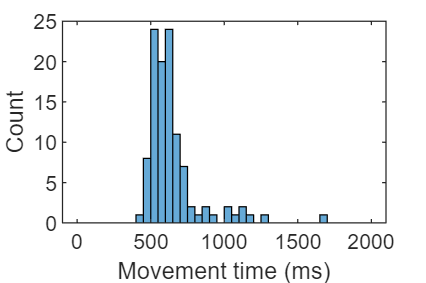

FP_correct_choice   = zeros(1, length(t_choice)); % find out choice_in FP associated with each reward
Port_correct_choice = zeros(1, length(t_choice)); % find out choice_in Port associated with each reward

mt_correct          = zeros(1, length(t_choice));
for i = 1:length(t_choice)
    dt = t_choice(i) - t_correct_cent_out;
    dt = dt(dt>tmin & dt<tmax); % reward must be collected within 2 sec after a correct cent_out
    if ~isempty(dt)
        mt_correct(i) = dt(end);
        ind = find(t_correct_cent_out==t_choice(i)-dt(end));
        if ~isempty(ind)
            FP_correct_choice(i)   = FPs_correct(ind);
            Port_correct_choice(i) = Ports_correct(ind);
        else
            disp('Not found')
        end
    else
        mt_correct(i) = NaN;
    end
end

t_correct_choice = t_choice(~isnan(mt_correct));
mt_correct       = mt_correct(~isnan(mt_correct));
FP_correct_choice   = FP_correct_choice(~isnan(mt_correct));
Port_correct_choice = Port_correct_choice(~isnan(mt_correct));
% Check movement time distribution
Edges = (0:50:2000);
figure(45); clf; set(gcf, 'Units', 'Centimeters', 'Position', [5 5 6 4]);
histogram(mt_correct, Edges);
xlabel('Movement time (ms)');
ylabel('Count');


% sort choice according to FP and Port
t_correct_choice_sorted = cell(nFPs, nPorts);
mt_correct_sorted       = cell(nFPs, nPorts);
for i = 1:nFPs
    for j = 1:nPorts
        ind_ij = find(FP_correct_choice==TargetFPs(i) & Port_correct_choice==Ports(j));
        t_correct_choice_sorted{i,j} = t_correct_choice(ind_ij);
        mt_correct_sorted{i,j}       = mt_correct(ind_ij);

        % rank them
        [mt_correct_sorted{i,j}, ind_sort] = sort(mt_correct_sorted{i,j});
        t_correct_choice_sorted{i,j}       = t_correct_choice_sorted{i,j}(ind_sort);
    end
end
mt_correct = mt_correct_sorted;
t_correct_choice = t_correct_choice_sorted;


### 1.2.2 Non-rewarded choice poke (wrong or probe trials)

## 1.3 Align to trigger stimulus

%% Trigger
ind_triggers = find(strcmp(rb.Labels, 'Trigger'));
t_triggers   = shape_it(rb.EventTimings(rb.EventMarkers==ind_triggers)); % trigger time in ms.

triggers_types = cell(1, length(t_triggers));
triggers_FPs   = zeros(1, length(t_triggers));
triggers_Ports = zeros(1, length(t_triggers));
triggers_RTs   = nan(1, length(t_triggers)); % reaction time (used for ranking later)

for i =1:length(t_triggers)
    it_trigger = t_triggers(i);
    % find the most recent cent_in
    ind_recent_cent_in = find(t_cent_in<it_trigger, 1, 'last');
    if ~isempty(ind_recent_cent_in) && abs(t_cent_in(ind_recent_cent_in)-it_trigger)<2500
        % check the condition
        triggers_types{i} = r.Behavior.Outcome{ind_recent_cent_in};
        triggers_FPs(i)   = r.Behavior.Foreperiods(ind_recent_cent_in);
        triggers_Ports(i) = r.Behavior.PortCorrect(ind_recent_cent_in);
        ind_following_cent_out = find(t_cent_out>it_trigger, 1, 'first');
        if ~isempty(ind_following_cent_out)
            triggers_RTs(i) = t_cent_out(ind_following_cent_out) - it_trigger;
        end
    else
        triggers_types{i} = 'NaN';
        triggers_FPs(i)   = NaN;
        triggers_Ports(i) = NaN;
    end
end

t_triggers_late = t_triggers(strcmp(triggers_types, 'Late'));
FP_triggers_late = triggers_FPs(strcmp(triggers_types, 'Late'));
triggers_RTs_late = triggers_RTs(strcmp(triggers_types, 'Late'));
[triggers_RTs_late, ind_sorted] = sort(triggers_RTs_late);
t_triggers_late = t_triggers_late(ind_sorted);
FP_triggers_late = FP_triggers_late(ind_sorted);

% trigger according to FPs
t_triggers_sort  = cell(nFPs, nPorts);
RT_triggers_sort = cell(nFPs, nPorts);

for i = 1:nFPs
    for j = 1:nPorts
        % sort trigger (to plot)
        t_triggers_sort{i,j}  = t_triggers(strcmp(triggers_types, 'Correct') & triggers_FPs==TargetFPs(i) & triggers_Ports==Ports(j));
        RT_triggers_sort{i,j} = triggers_RTs(strcmp(triggers_types, 'Correct') & triggers_FPs==TargetFPs(i) & triggers_Ports==Ports(j));
        % sort according to reaction time
        [RT_triggers_sort{i,j}, ind_sorted] = sort(RT_triggers_sort{i,j});
        t_triggers_sort{i,j} = t_triggers_sort{i,j}(ind_sorted);
    end
end


## 1.4 Align to init-in and init-out

# 2 Check compute range

%% Check ComputeRange
if ~isempty(ComputeRange)
    t_cent_in(t_cent_in<ComputeRange(1) | t_cent_in>ComputeRange(2))=[];
    
    for i=1:nFPs
        to_remove = find(t_correct_cent_in_sorted{i}<ComputeRange(1) | t_correct_cent_in_sorted{i}>ComputeRange(2) | t_correct_cent_out_sorted{i}<ComputeRange(1) | t_correct_cent_out_sorted{i}>ComputeRange(2));
        t_correct_cent_out_sorted{i}(to_remove) = [];
        rt_cent_out_sorted{i}(to_remove)        = [];
        t_correct_cent_in_sorted{i}(to_remove)  = [];
        rt_cent_in_sorted{i}(to_remove)         = [];
    end
    to_remove_premature = find(t_premature_cent_in<ComputeRange(1) | t_premature_cent_in>ComputeRange(2) | t_premature_cent_out<ComputeRange(1) | t_premature_cent_out>ComputeRange(2));
    t_premature_cent_in(to_remove_premature)         = [];
    HD_premature_cent_in(to_remove_premature)  = [];
    FP_premature_cent_in(to_remove_premature)       = [];
    t_premature_cent_out(to_remove_premature)        = [];
    HD_premature_cent_out(to_remove_premature) = [];
    FP_premature_cent_out(to_remove_premature)      = [];
    
    to_remove_late = find(t_late_cent_in<ComputeRange(1) | t_late_cent_in>ComputeRange(2) | t_late_cent_out<ComputeRange(1) | t_late_cent_out>ComputeRange(2));
    t_late_cent_in(to_remove_late)         = [];
    late_duration_cent_in(to_remove_late)  = [];
    FPs_late_cent_in(to_remove_late)       = [];
    t_late_cent_out(to_remove_late)        = [];
    late_duration_cent_out(to_remove_late) = [];
    FPs_late_cent_out(to_remove_late)      = [];
    
    for i=1:nFPs
        to_remove_rewardpokes =  find(t_reward_pokes{i}<ComputeRange(1) | t_reward_pokes{i}>ComputeRange(2));
        t_reward_pokes{i}(to_remove_rewardpokes) = [];
        mt_correct{i}(to_remove_rewardpokes) = [];
    end
    
    to_remove_nonrewardpokes = find(t_nonreward_pokes<ComputeRange(1) | t_nonreward_pokes>ComputeRange(2));
    t_nonreward_pokes(to_remove_nonrewardpokes) = [];
    move_time_nonreward(to_remove_nonrewardpokes) = [];
    
    for i = 1:nFPs
        to_remove = find(t_triggers_sort{i}<ComputeRange(1) | t_triggers_sort{i}>ComputeRange(2));
        t_triggers_sort{i}(to_remove) = [];
        RT_triggers_sort{i}(to_remove) = [];
    end
    
    to_remove_trigger_late = find(t_triggers_late<ComputeRange(1) | t_triggers_late>ComputeRange(2));
    t_triggers_late(to_remove_trigger_late) = [];
    triggers_RTs_late(to_remove_trigger_late) = [];
    FP_triggers_late(to_remove_trigger_late) = [];
end


# 3 Summerize

%% Summarize
PSTHOut.ANM_Session = {r.BehaviorClass.Subject, r.BehaviorClass.Session};

% Cent-In
PSTHOut.CentIn.Labels = [repmat({'Correct'}, 1, numel(t_correct_cent_in_sorted)), 'Premature', 'Late', 'All'];

PSTHOut.CentIn.Time = cell(1, length(PSTHOut.CentIn.Labels));
PSTHOut.CentIn.Time(1:numel(t_correct_cent_in_sorted)) = t_correct_cent_in_sorted;
PSTHOut.CentIn.Time(numel(t_correct_cent_in_sorted)+1) = {t_premature_cent_in};
PSTHOut.CentIn.Time(numel(t_correct_cent_in_sorted)+2) = {t_late_cent_in};
PSTHOut.CentIn.Time(numel(t_correct_cent_in_sorted)+3) = {t_cent_in};

PSTHOut.CentIn.FP                = {TargetFPs, FP_premature_cent_in, FPs_late_cent_in};
PSTHOut.CentIn.RT_Correct        = rt_cent_in_sorted;
PSTHOut.CentIn.HoldDur.Premature = HD_premature_cent_in;
PSTHOut.CentIn.HoldDur.Late      = late_duration_cent_in;

% Cent-Out
PSTHOut.CentOut.Labels = [repmat({'Correct'}, 1, numel(t_correct_cent_in_sorted)), 'Premature', 'Late'];
PSTHOut.CentOut.Time   = cell(1, length(PSTHOut.CentOut.Labels));
PSTHOut.CentOut.Time(1:numel(t_correct_cent_in_sorted))  = t_correct_cent_out_sorted;
PSTHOut.CentOut.Time(numel(t_correct_cent_in_sorted)+1)  = {t_premature_cent_out};
PSTHOut.CentOut.Time(numel(t_correct_cent_in_sorted)+2)  = {t_late_cent_out};

PSTHOut.CentOut.FP                = {TargetFPs, FP_premature_cent_out, FPs_late_cent_out};
PSTHOut.CentOut.RT_Correct        = rt_cent_out_sorted;
PSTHOut.CentOut.HoldDur.Premature = HD_premature_cent_out;
PSTHOut.CentOut.HoldDur.Late      = late_duration_cent_out;

% Choice-In
PSTHOut.ChoiceIn.Time                    = t_choice;
% PSTHOut.ChoiceIn.RewardPoke.Time         = t_reward_pokes; % it is a cell now!
% PSTHOut.ChoiceIn.RewardPoke.Move_Time    = move_time;      % it is a cell now!
% PSTHOut.ChoiceIn.NonrewardPoke.Time      = t_nonreward_pokes;
% PSTHOut.ChoiceIn.NonrewardPoke.Move_Time = move_time_nonreward;

% Trigger
PSTHOut.Triggers.Labels                         = {'TriggerTime_DifferentFPs' 'TriggerTime_Late'};
PSTHOut.Triggers.Time                           = cell(1, numel(t_triggers_sort)+1);
PSTHOut.Triggers.Time(1:numel(t_triggers_sort)) = t_triggers_sort;

Conversion to double from cell is not possible.

PSTHOut.Triggers.Time(end)                      = {t_triggers_late};

PSTHOut.Triggers.RT                             = [RT_triggers_sort(:)', {triggers_RTs_late}];
PSTHOut.Triggers.FP                             = {repmat(TargetFPs, 1, 2), FP_triggers_late};
PSTHOut.Triggers.Port                           = {reshape(repmat(Ports, 3, 1), 1, []), FP_triggers_late};

% PSTHOut.OptoEpochs.Begs                             =     t_opto_begs;
% PSTHOut.OptoEpochs.Ends                             =     t_opto_ends;

PSTHOut.SpikeNotes                              = r.Units.SpikeNotes;


# 4 Compute PSTH

%% Check how many units we need to compute
% derive PSTH from these
% go through each units if necessary
for iku = 1:length(ku_all)
    ku = ku_all(iku);
    if ku>length(r.Units.SpikeTimes)
        disp('##########################################')
        disp('########### That is all you have ##############')
        disp('##########################################')
        return
    end
    disp('##########################################')
    disp(['Computing this unit: ' num2str(ku)])
    disp('##########################################')
    PSTHOut.PSTH(iku) = Spikes.SRT.ComputePlotPSTH(r, PSTHOut, ku,...
        'CentInTimeDomain', CentInTimeDomain, ...
        'CentInTimeDomain', CentOutTimeDomain, ...
        'RewardTimeDomain', ChoiceTimeDomain,...
        'TriggerTimeDomain', TriggerTimeDomain,...
        'ToSave', ToSave);
end

if takeall
    
    r.PSTH.Events.cent_in    = PSTHOut.cent_in;
    r.PSTH.Events.cent_out   = PSTHOut.cent_out;
    r.PSTH.Events.Pokes      = PSTHOut.Pokes;
    r.PSTH.Events.Triggers   = PSTHOut.Triggers;
    r.PSTH.Events.OptoEpochs = PSTHOut.OptoEpochs;
    r.PSTH.Events.cent_in    = PSTHOut.cent_in;
    r.PSTH.PSTHs             = PSTHOut.PSTH;
    
    r_name = Spikes.r_name;
    save(r_name, 'r');
    psth_new_name             =      [r.BehaviorClass.Subject, '_', r.BehaviorClass.Date, '_PSTHs.mat'];
    save(psth_new_name, 'PSTHOut');
    try
        % C:\Users\jiani\OneDrive\00_Work\03_Projects\05_Physiology\PSTHs
        thisFolder = fullfile(findonedrive, '00_Work', '03_Projects', '05_Physiology', 'Data', 'PETHs', r.BehaviorClass.Subject);
        if ~exist(thisFolder, 'dir')
            mkdir(thisFolder);
        end
        copyfile(psth_new_name, thisFolder);
    end
end

